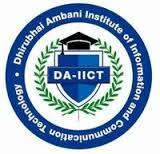

# CT216: Introduction to Communication Systems

# Lab 4 (Experiments): Definition of Information and Information Transfer over a Communication Channel

The computer simulation based experiments in the Lab ask you to perform experiments to obtain understanding how much information can be transmitted reliably (i.e., without errors) even when the channel over which the information is transmitted is noisy. One of the main purposes of this Lab is for you to experiment with the values of $q$ and $p$ parameters of the C-disease problem, i.e., the BSC($p$) channel, and observe and plot the resulting entropies numerically and graphically. 

You are asked to perform the experiments using the following code (extra credits if you think of and devise new experiments and develop the Matlab/Python code). Show the results and make your observational/insightful comments regarding these results.

**This entire programming-based experiments section of Lab 4 carries 40 marks.**

# A Model of Causes and Their Influence on the Effects

In this exercise we will consider the binary case, i.e., the cause is binary and the observed effect is also binary

### Step 1: Define a Bernouilli Source

Define the Bernouilli($q$) source X and calculate its entropy. 

q =0.7;
pX = [q 1-q];
H_X = entropy_function(pX)

H_X = 0.8813

### Step 2: Define a the channel and its likelihood function

Define the likelihood function of the binary noisy channel. 

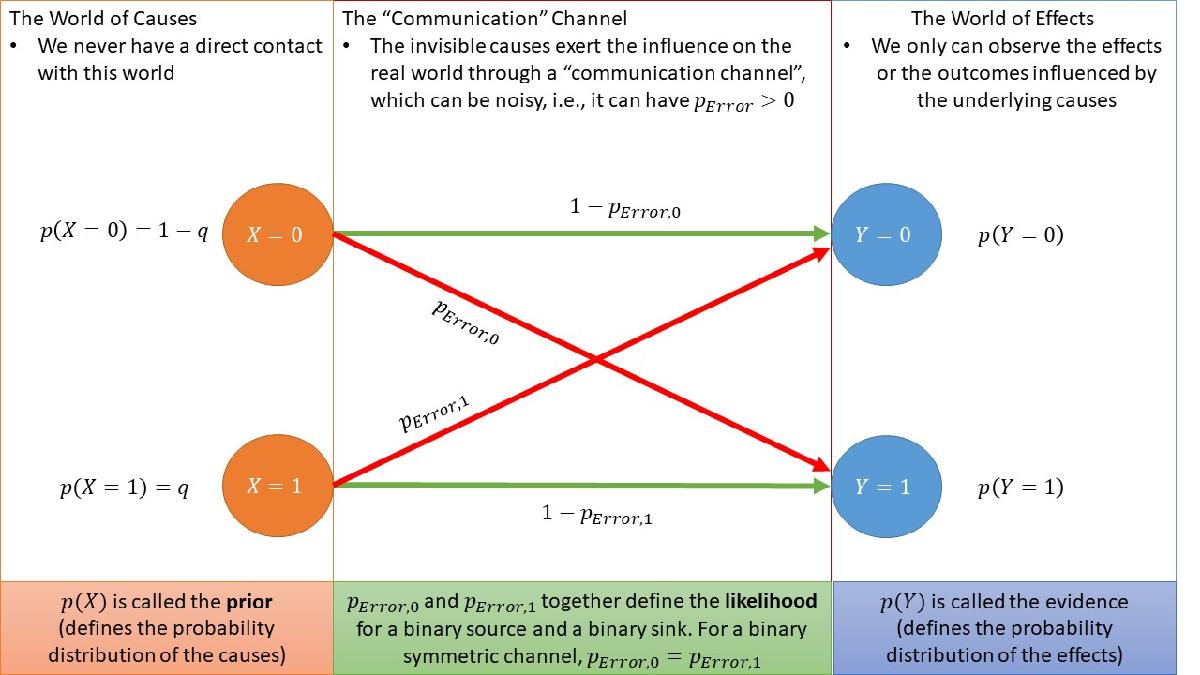

The first element of pYgivenX0 corresponds to $Y = 0$ and the second element corresponds to $Y = 1$, and likewise, the first element of pYgivenX1 corresponds to $Y = 0$ and the second element corresponds to $Y = 1$.

pError0 =0.21;
pYgivenX0 = [1-pError0 pError0]; % the likelihood function, i.e., the prob of [Y=0, Y = 1] when X = 0

pError1 =0.42;
pYgivenX1 = [pError1 1-pError1]; % the likelihood function [Y=0, Y = 1] when X = 1

### Step 3: Calculate the posterior on the source: the direct method

The (marginal) probability of the effect: i.e., the evidence or the probability $p(Y)$, is calculated using the rule of marginalization of the joint probability.

pY(1) = pYgivenX0(1)*pX(1)+pYgivenX1(1)*pX(2); % This is prob of Y = 0
pY(2) = pYgivenX0(2)*pX(1)+pYgivenX1(2)*pX(2); % This is prob of Y = 1

The posterior is calculated using the Bayes' rule:

pXgivenY0 = [pX(1)*pYgivenX0(1) pX(2)*pYgivenX1(1)]/pY(1)

pXgivenY0 =     0.8426    0.1574


pXgivenY1 = [pX(1)*pYgivenX0(2) pX(2)*pYgivenX1(2)]/pY(2)

pXgivenY1 =     0.5075    0.4925


### Step 4: Calculate the Conditional Entropy and the Information Transfer

The entropy of the RVs $\tilde{X}_n$ , where $n = 0$ or $1$, is called the conditional entropy (the entropy of $X$ conditioned on an observation $Y = n$). This topic of conditional entropy is explained on **Slides 68 onward of Lecture 2 Probability Theory slides posted on Google Classroom**. Please read these slides before experimenting with the following code. 

Note that $H(X)$ signifies the uncertainty at the receiver regarding the state $X = 0$ or $X = 1$ of the transmitter. The purpose of communication is to reduce this uncertainty at the receiver after observation of $Y$ (e.g., we say that we have received information only if the output of the communication channel reduces our uncertainty about the state of the transmitter. Can you think of some real-world real-life examples of this). However, $H(\tilde{X}_n)$ is the metric (a single scalar value) which succinctly captures the uncertainty at the receiver regarding $X$ after observation of $Y_n$. Using this argument, Shannon defined the information transfer over a noisy communication channel as the *difference* between the unconditional and the conditional entropies. The specific name is *Mutual Information *and it is defined as $I(X; Y) = H(X) - H(\tilde{X})$, where $H(\tilde{X})$ is the average of $H(\tilde X_n)$ over all values $Y = n$.

H_X

H_X = 0.8267

H_XgivenY0 = entropy_function(pXgivenY0)

H_XgivenY0 = 0.6280

InformationTransfer_givenY0 = H_X - H_XgivenY0

InformationTransfer_givenY0 = 0.1987


H_X

H_X = 0.8267

H_XgivenY1 = entropy_function(pXgivenY1)

H_XgivenY1 = 0.9998

InformationTransfer_givenY1 = H_X - H_XgivenY1

InformationTransfer_givenY1 = -0.1731


H_X

H_X = 0.8267

H_XgivenY = pY(1)*H_XgivenY0 + pY(2)*H_XgivenY1

H_XgivenY = 0.7419

InformationTransfer = H_X - H_XgivenY

InformationTransfer = 0.0849

### Step 5: Evaluate the information transfer for varying values of $p_{Error} = p_{Error,0} = p_{Error,1}$

This step is similar to what we have done earlier for the Entropy function. There we varied $q$ parameter and evaluated the Entropy of the Information source for each value of $q$. The evaluated Entropy was plotted as a function of $q$.

In this section, we now repeat the same procedure, except the goal is to plot the information transfer capability of the BSC($p_{Error}$) in transferring the information generated by the Bernouilli($q$) source. This plot is obtained as a function of $p_{Error}$ for a specified $q$ value.

q =0.5;
pX = [1-q q];
H_X = entropy_function(pX)

H_X = 1

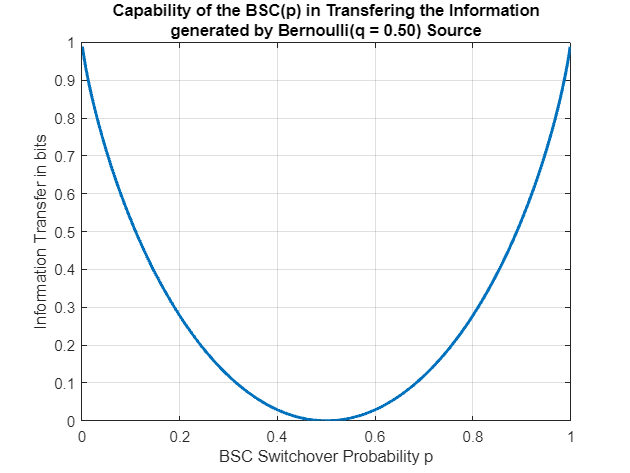


pErrorVec = 0:1e-3:1;
Info_X_Y = 0*pErrorVec;
kk = 0;
for pError = pErrorVec
    kk = kk+1;
    pYgivenX0 = [1-pError pError]; 
    pYgivenX1 = [pError 1-pError];
    pY(1) = pYgivenX0(1)*pX(1)+pYgivenX1(1)*pX(2);
    pY(2) = pYgivenX0(2)*pX(1)+pYgivenX1(2)*pX(2);
    pXgivenY0 = [pX(1)*pYgivenX0(1) pX(2)*pYgivenX1(1)]/pY(1);
    pXgivenY1 = [pX(1)*pYgivenX0(2) pX(2)*pYgivenX1(2)]/pY(2);
    H_X_givenY0 = entropy_function(pXgivenY0);
    H_X_givenY1 = entropy_function(pXgivenY1);
    H_X_givenY = pY(1)*H_X_givenY0 + pY(2)*H_X_givenY1;
    Info_X_Y(kk) = H_X - H_X_givenY;
end
plot(pErrorVec,Info_X_Y,linewidth=2)
xlabel('BSC Switchover Probability p'); ylabel('Information Transfer in bits')
title({'Capability of the BSC(p) in Transfering the Information',sprintf('generated by Bernoulli(q = %1.2f) Source',q)}); grid

%{
In this section we can play with the values of p and q and perror and
qerror and can realise the graph with the analytic result that we got from
the analytical questions.
%}

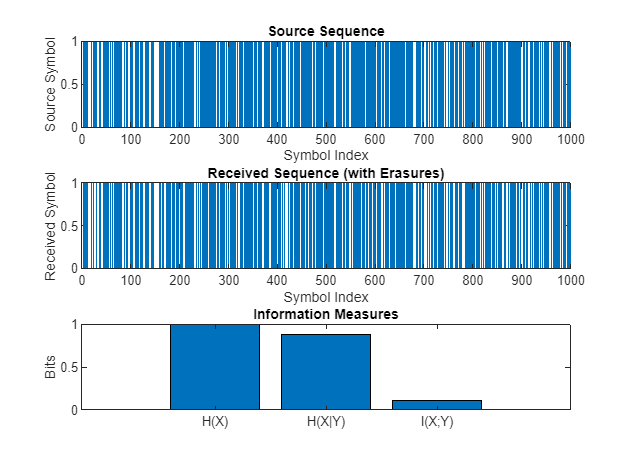


% Binary Erasure Channel Simulation and Information Measures

% Parameters
p_erasure = 0.1; % Probability of erasure

% Generate random binary source
source_length = 1000;
source = randi([0, 1], 1, source_length);

% Simulate Binary Erasure Channel
received = source;
erasure_indices = rand(1, source_length) < p_erasure;
received(erasure_indices) = NaN; % Erasure symbol

% Calculate Entropy H(X)
prob_source_0 = sum(source == 0) / source_length;
prob_source_1 = sum(source == 1) / source_length;
entropy_X = - (prob_source_0 * log2(prob_source_0 + eps) + prob_source_1 * log2(prob_source_1 + eps));

% Calculate Conditional Entropy H(X|Y)
prob_erasure = sum(~isnan(received)) / source_length;
conditional_entropy_X_given_Y = prob_erasure;

% Calculate Mutual Information I(X;Y)
mutual_information = 1 - prob_erasure;

% Plotting
figure;

subplot(3, 1, 1);
stem(source, 'Marker', 'none');
title('Source Sequence');
xlabel('Symbol Index');
ylabel('Source Symbol');

subplot(3, 1, 2);
stem(received, 'Marker', 'none');
title('Received Sequence (with Erasures)');
xlabel('Symbol Index');
ylabel('Received Symbol');

subplot(3, 1, 3);
bar([entropy_X, conditional_entropy_X_given_Y, mutual_information]);
xticks(1:3);
xticklabels({'H(X)', 'H(X|Y)', 'I(X;Y)'});
title('Information Measures');
ylabel('Bits');


% Display values
fprintf('Entropy H(X): %.4f bits\n', entropy_X);

Entropy H(X): 0.9992 bits


fprintf('Conditional Entropy H(X|Y): %.4f bits\n', conditional_entropy_X_given_Y);

Conditional Entropy H(X|Y): 0.8840 bits


fprintf('Mutual Information I(X;Y): %.4f bits\n', mutual_information);

Mutual Information I(X;Y): 0.1160 bits